clc; clear all; close all;
A=[-13.8170 0 -0.205 0;
12.7753 -1.0417 0.205 0;
11.1784 0 -2.8154 1.7914;
0 0 3.0811 -3.8311];
B=[0.3083 0;-0.3083 0;-0.0542 0;0 -1.5375];
C=[0 1 0 0;0 0 1 0]

C =      0     1     0     0
     0     0     1     0


D=zeros(2);

% Parámetros del MPC
Ts = 0.1;         % Tiempo de muestreo
N = 5;            % Horizonte de predicción
Qy = diag([100;1000]);         % Penalización de la salida
R = diag([0.001;0.001])          % Penalización del control

R = 1.0e-03 *

    1.0000         0
         0    1.0000


yref = [1;1]         % Referencia deseada

yref =      1
     1


x0 = [0;0;0;0];      % Estado inicial
Qf = 1000*Qy;  

C' * Qy *C

ans =            0           0           0           0
           0         100           0           0
           0           0        1000           0
           0           0           0           0



% Llamada a la función MPC
[X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yref, x0, Qf);

nu = 2

Qbig = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         

Qbig = 1.0e+06 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         

q =            0
        -100
       -1000
           0
           0
        -100
       -1000
           0
           0
        -100


ze =      0     0     0     0


zeB =      0     0


Xmax2 =      0     0     1     0


Aineq =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0   

bineq =     0.9900
    0.9900
    0.9900
    0.9900
    0.9900
    1.0200
    1.0200
    1.0200
    1.0200
    1.0200



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =    -0.9627
    0.9627
    0.9448
   14.6658
   -0.9900
    0.9900
    1.0200
    0.4107
   -0.9657
    0.9657


X

X =    -0.9627   -0.9900   -0.9657   -0.9900   -0.9900
    0.9627    0.9900    0.9657    0.9900    0.9900
    0.9448    1.0200    0.9755    1.0133    1.0000
   14.6658    0.4107   10.6902    3.2628    8.8437


U

U =   -57.3015  -43.9831  -42.3548  -43.9975  -43.7530
 -114.0343   77.4668  -79.8180   33.7340  -49.9737


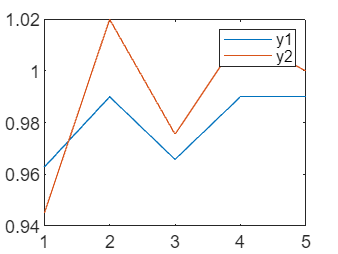

figure
plot(X(2,:));  hold on;
legend('posicion 1')
plot(X(3,:))
legend('Posision 2')
legend('y1','y2')

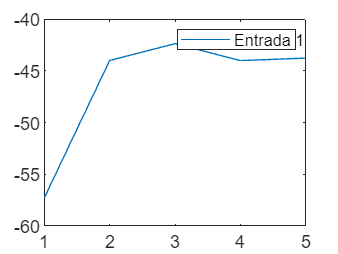


figure
plot(U(1,:));  
legend('Entrada 1')

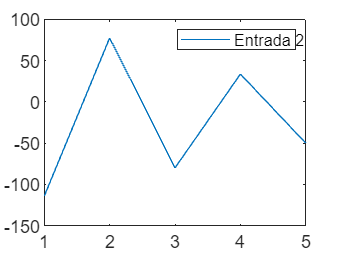


figure
plot(U(2,:))
legend('Entrada 2')

function [X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yrefk, x0, Qf, constraints)
    % Convertir sistema continuo a discreto (ZOH)
    sysc = ss(A, B, C, D);
    sysd = c2d(sysc, Ts, 'zoh');
    Ad = sysd.A;
    Bd = sysd.B;
    
    % Dimensiones del sistema
    nx = size(A, 1); % Número de estados
    nu = size(B, 2) % Número de entradas (MIMO)
    ny = size(C, 1); % Número de salidas (MIMO)

    % Función de costo
    Qbig = blkdiag(kron(eye(N), C' * Qy * C), kron(eye(N), R))
    Qbig(nx*(N-1)+(1:nx),nx*(N-1)+(1:nx))=C'*Qy*C+C'*Qf*C
    
    % Asegurar que yrefk tenga dimensiones correctas
    if size(yrefk, 2) ~= 1
        error('yrefk debe ser un vector columna de tamaño (ny, 1)')
    end
    q = -[repmat(C' * Qy * yrefk, N, 1); zeros(N*nu, 1)];
    q(nx*(N-1)+(1:nx),1)=-C'*Qy*yrefk-C'*Qf*yrefk
    
    % Restricciones de igualdad 

    Aeq = zeros(N * nx, N * (nx + nu));
    beq = zeros(N * nx, 1);

    for k = 1:N
        Aeq((k-1)*nx+1:k*nx, (k-1)*nx+1:k*nx) = -eye(nx);
        if k == 1
            Aeq(1:nx, 1:nx) = -eye(nx);
            Aeq(1:nx, nx*N+1:nx*N+nu) = Bd;
            beq(1:nx) = -Ad * x0;
        else
            Aeq((k-1)*nx+1:k*nx, (k-2)*nx+1:(k-1)*nx) = Ad;
            Aeq((k-1)*nx+1:k*nx, nx*N+(k-1)*nu+1:nx*N+k*nu) = Bd;
        end
    end


    % Restricciones de control y estados
   %  Aineq = [];
   %  bineq = [];
   % 
   %  Xmax = [0;0.99;1.02;0];
   %  Xmin = [0;0;0;0]
   % 
   % % Umax = [10;8]
   % % Umin = [-7;NaN] %----> NaN o []
   % %[Aineq, bineq] = restricciones(nx, nu, N,Xmin,Xmax, [], [])
   % 

    ze = zeros(1,nx)
    zeB = zeros(1,nu)
    
    Umax = [1]; %-----> tamaño nu numero de entradas en fila
    Xmax = [0 1 0 0]; %----> tamaño de estados fila
    Xmax2 = [0 0 1 0]
    Aineq=[
          Xmax ze ze ze ze  zeB zeB zeB zeB zeB;
          ze Xmax ze ze ze  zeB zeB zeB zeB zeB;
          ze ze Xmax ze ze  zeB zeB zeB zeB zeB;
          ze ze ze Xmax ze  zeB zeB zeB zeB zeB;
          ze ze ze ze Xmax  zeB zeB zeB zeB zeB;
    
          Xmax2 ze ze ze ze  zeB zeB zeB zeB zeB;
          ze Xmax2 ze ze ze  zeB zeB zeB zeB zeB;
          ze ze Xmax2 ze ze  zeB zeB zeB zeB zeB;
          ze ze ze Xmax2 ze  zeB zeB zeB zeB zeB;
          ze ze ze ze Xmax2  zeB zeB zeB zeB zeB;]
    
    bineq=[ 0.99*ones(N,1); % ---> primera restriccion
           1.02*ones(N,1);] % -----> segunda restriccion

    % Resolver el problema de optimización cuadrática
    z = quadprog(Qbig, q, Aineq, bineq, Aeq, beq)

    % Extraer X y U
    X = reshape(z(1:nx*N), nx, N);
    U = reshape(z(nx*N+1:end), nu, N);
end

function [Aineq, bineq] = restricciones(nx, nu, N, Xmin, Xmax, Umin, Umax)
    nvar = nx * N + nu * N;
    
    Aineq = [];
    bineq = [];
    
    %% Restricciones para los estados
    for t = 1:N
        for i = 1:nx
            idx = (t-1)*nx + i; 
            if ~isempty(Xmax)
                if ~( Xmax(i)==0 && ~isempty(Xmin) && Xmin(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Xmax(i)];
                end
            end

            if ~isempty(Xmin)
                if ~( Xmin(i)==0 && ~isempty(Xmax) && Xmax(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Xmin(i)];
                end
            end
        end
    end
    
    %% Restricciones para las entradas
    for t = 1:N
        for j = 1:nu
            idx = nx * N + (t-1)*nu + j; 
            if ~isempty(Umax)
                if ~( Umax(j)==0 && ~isempty(Umin) && Umin(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Umax(j)];
                end
            end
            
            if ~isempty(Umin)
                if ~( Umin(j)==0 && ~isempty(Umax) && Umax(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Umin(j)];
                end
            end
        end
    end
end
